# Loops

Computers have to be told explicitly how to make decisions. One type of decision which is common in computer programming regards iteration, that is whether to repeat a section of code again. Looping code is generally present when the same computation is going to be applied to different data each time or when the output from the loop is fed back as input to the loop code for the next iteration. This script will present two different types of looping instructions: `for` loops and `while` loops. What kind of loop do you think is shown here?

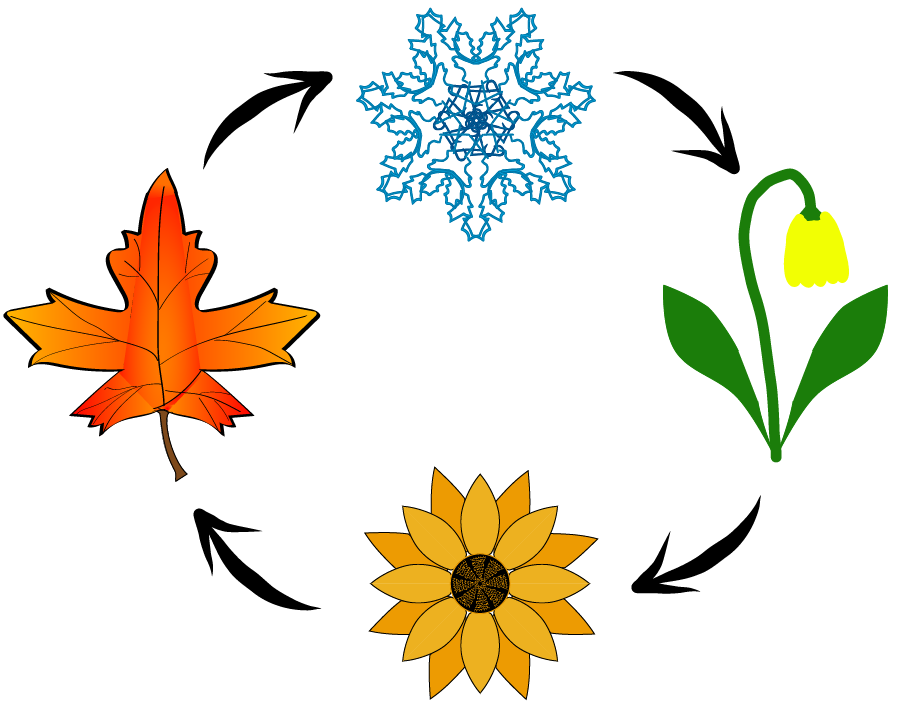

Loops are one of the most important time-saving methods in programming because you only need to write the instructions once but the computer can run the instructions many times. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. If you put your script in a different mode such as Code Hidden, you can return to Output Inline by going to the **View** tab of the MATLAB toolstrip and in the **View** section select **Output Inline**. Alternately, you can select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB, as concepts and commands are introduced together, but some familiarity with the Live Editor environment was introduced in [programmingIntroduction.mlx](matlab:open('./programmingIntroduction.mlx')). A brief summary of the tools, tips, and suggestions from each script is gathered in [Collected Pro Tips](matlab:open('./CollectedProTips.mlx')).

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running all code blocks.

## Loops

The two most common types of loops are `for` loops and `while` loops. Although it is not always the case with programming, the names here do give you a fairly clear indication of how they work from the everyday meaning of the words.

### For Loops

A `for` loop is a clearly delimited section of code that will run a set number of times, as directed by the programmer. 

The number of repetitions can either be set directly, e.g. by naming an index value such as `k` and then providing start and end values. Run the code block to observe the changing value of the index each time the body of the loop runs. 

for k = 1:10
    str = "The current value of the loop index is " + k
end

Alternately, you can define a loop index in terms of any other vector of values. If you start with the 1x7 vector `days` that contains a string for each day of the week, the loop will execute the body code with the index set to each vector element one after another. Run the code block below to observe the changing value of the index each time the body of the loop runs.

daysOfWeek = ["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"];
for d = daysOfWeek
    str = "Today is " + d + ", tomorrow is another day."
end

The latter form is sometimes called a `foreach` loop, because it executes for each element of the indexing set. 

Some programming languages require the programmer to explicitly update the index value within the loop while others, such as MATLAB, will handle updating the index value automatically for each iteration. 

#### ** Exercise 1.**

Write a `for` loop that will print out the squares of the first 25 positive integers.

% Write your code here. Replace this comment with a more appropriate one.
% You can compare your values to the first 25 squares given as
% First25Squares in the Reference Solutions section


#### ** Exercise 2.**

Write a `for` loop that will tell at least three "Knock Knock" jokes. The jokes are included in the Reference Solutions section so you know what you are aiming to reproduce. If you would prefer to write additional "Knock Knock" jokes, feel free (knock yourself out). If you need a review of [string concatenation](matlab:open('./programmingData.mlx')) or [vector indexing](matlab:open('./programmingArrays.mlx')), you can review the relevant script or refer to the [Collected Pro Tips](matlab:open('./CollectedProTips.mlx')) reference collection.

opening = "Knock Knock!" + newline + "Who's there?";
answer = ["Orange" "Who" "Boo"];
punchline = ["Orange you glad I didn't say banana?" "I didn't know you were an owl!" "Please don't cry!"];


### While Loops

A `while` loop begins each execution by asking a question. If that question evaluates as a boolean `true`, then the code within the `while` loop will run. If that question evaluates as a boolean `false`, then the loop terminates. Be careful, because this command can make it simple to write infinite loops, that is code that will run forever because the conditional question always evaluates to `true`. 

  **Try**. Run the code below. Then try changing the initial value of `k=1,` the termination condition, `k < 1337`, and the loop body, `k = 2*k`. 

- What happens if the initial value is `k=25`? Or `k=.001`? Or `k=-2`?

- What happens if the termination condition is (`k < 4096)`? Or (`k < 4e100)`?` O`r` (k == 1)`?` O`r (`k > -10)`?

- What happens if the loop body is `k=k^2`? Or `k=k+5`? Or `k=6`?

Please leave the `pause(n)` in your loop so that if your code runs longer than you intend, you can terminate execution by pressing Ctrl-C or by clicking the **Stop** button in the **Live Editor **tab. The `n` in `pause(n)` is the number of seconds to pause before continuing. It must be a nonnegative number. Once you have investigated the output to your satisfaction, for readability of the script you may want to click the **Clear all Output** button in the **View **tab.

% Print powers of 2
k = 1;
while k < 1337 
    k = 2*k
    pause(0)
end

In this case, your control variable, `k`, must be changed for each iteration of the code because otherwise you can get stuck in an infinite loop that will run forever until you manage to kill execution of the program. In some cases interrupting execution is simple, but others can require exiting your development environment or even rebooting your system entirely. 

#### ** Exercise 3.**

Use a `while` loop to compute all the Fibonacci numbers less than `1e5` and store them in a variable called `fib`. Comment your code appropriately. 

The Fibonacci numbers can be generated by the recursive relation 

$f_n = f_{n-1}+f_{n-2}$.

That is each Fibonacci number is the sum of the previous two Fibonacci numbers. The first two Fibonacci numbers are both 1. 

If you need to review, vector concatenation and indexing were covered in [Arrays](matlab:open('./programmingArrays.mlx')), and are summarized in [Collected Pro Tips](matlab:open('./CollectedProTips.mlx')). You can check your solution by comparing to the values of `FibLess1e5` in the Reference Solutions section.

% Initialize fib with the first two Fibonacci numbers 
fib = [1 1];


## Moving On

The next step is to get more practice with all of the conditional logic you have been learning about. You can practice these ideas in [programmingChaosGameProject.mlx](matlab:open('./programmingChaosGameProject.mlx')).

## Reference Solutions

#### Exercise 1

First25Squares = [1 4 9 16 25 36 49 64 81 100 121 144 169 196 225 256 289 324 361 400 441 484 529 576 625];

  **Pro-tip**. In practice, many simple for loops can be treated as parallel vector operations which is almost always faster. In this case it would be 

#### Exercise 2

**Jokes:**

Knock Knock!

Who's there?

Orange

Orange who?

Orange you glad I didn't say banana?

Knock Knock!

Who's there?

Who

Who who?

I didn't know you were an owl!

Knock Knock!

Who's there?

Boo

Boo who?

Please don't cry!

#### Exercise 3

FibLess1e5 = [1 1 2 3 5 8 13 21 34 55 89 144 233 377 610 987 1597 2584 4181 6765 10946 17711 28657 46368 75025];